# SSH MODEL 

#### BAND STRUCTURE DEMO

REGIME 1: WEAKLY COUPLED DIMER: |v| << |w|

REGIME 2: STRONGLY COUPLED DIMER: |v| >> |w|

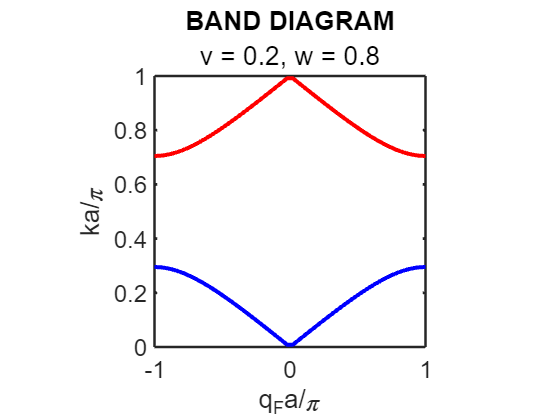

close all
clear all
clc

% Acoustic pseudo-energy is defined as E(k) = cos(ka/2);
%
N = 50;
qa = linspace(-pi,pi,N); %q_Floquet
v =0.2; % intracell coupling
w = 1 - v; % intercell coupling
gamma_0 = -0; %losses



ka_up_0 = real(acos(gamma_0 + sqrt(v^2+w^2+2*v*w*cos(qa))));
ka_dn_0 = real(acos(gamma_0 - sqrt(v^2+w^2+2*v*w*cos(qa))));
ka_up_1 = real(acos(gamma_0 + sqrt(v^2+w^2+2*v*w*cos(qa)))) + pi ;
ka_dn_1 = real(acos(gamma_0 - sqrt(v^2+w^2+2*v*w*cos(qa)))) + pi ;

phi_up =  -angle(+sqrt(v^2+w^2+2*v*w*cos(qa))./(v+w*exp(-1i*(qa))));
phi_dn =  -angle(-sqrt(v^2+w^2+2*v*w*cos(qa))./(v+w*exp(-1i*(qa))));


%%% FIGURES %%%%%%%%%%%%%%%%%%%%%%%%%%%
close all

figure(2)
set(gca,'FontSize',18)
set(gca,'LineWidth',2)
box on
xlim([-1,1])
ylim([0,1])
hold on
plot(qa/pi,real(ka_up_0)/pi,'b-','LineWidth',3)
plot(qa/pi,real(ka_dn_0)/pi,'r-','LineWidth',3)
plot(qa/pi,ka_up_1/pi,'b-','LineWidth',3)
plot(qa/pi,ka_dn_1/pi,'r-','LineWidth',3)
%yline(omega_0,'--','\omega_0','LineWidth',2,'FontSize',18)
%yline(gamma_0,'--','','LineWidth',2,'FontSize',18)
hold off
%set(gca,'XTick',-pi:pi/2:pi)
%set(gca,'XTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'})
 
 
xlabel("q_Fa/\pi")
%ylabel("Unitcell Eigenfrequencies (\omega_0)")
ylabel("ka/\pi")
%legend('\omega_{-}','\omega_{+}')
title('BAND DIAGRAM', sprintf('v = %.1f, w = %.1f',[v,w]))

axis square

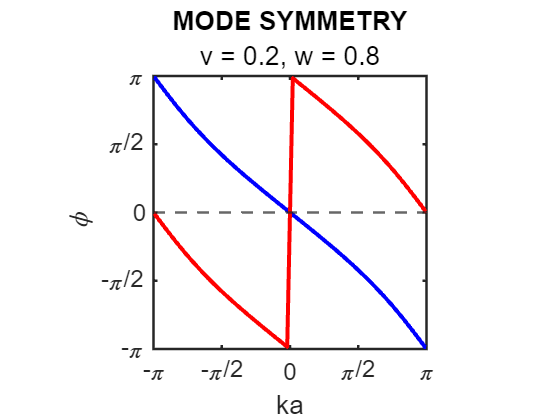


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
figure(3)
set(gca,'FontSize',18)
set(gca,'LineWidth',2)
box on
xlim([-pi,pi])
ylim([-pi,pi])
hold on
plot(qa,phi_up,'b-','LineWidth',3)
plot(qa,phi_dn,'r-','LineWidth',3)
%yline(0,'--','\omega_0','LineWidth',2,'FontSize',18)
yline(0,'--','','LineWidth',2,'FontSize',18)
hold off
set(gca,'XTick',-pi:pi/2:pi)
set(gca,'XTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'})

set(gca,'YTick',-pi:pi/2:pi)
set(gca,'YTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'})
 
xlabel("ka")
ylabel("\phi ")
%legend('\omega_{-}','\omega_{+}')
title('MODE SYMMETRY',sprintf('v = %.1f, w = %.1f',[v,w]))

axis square



%}

#### WINDING NUMBER DEMO

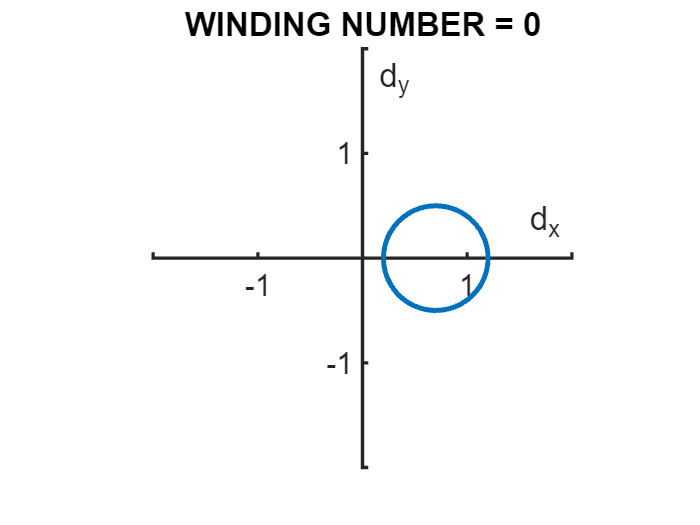

close all
v =0.7; %intracell coupling
w =0.5; %interell coupling

qa = linspace(-pi,pi,50);

dx = v + w*cos(qa) ;
dy = w*sin(qa);


zci = @(v) find(diff(sign(v))); %where cross zero
idx0 = zci(dx);

if v<w
    winding = 1;
else
    winding = 0;
end


figure(4)
hold on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.FontSize = 18  ;
ax.LineWidth = 2;

plot(dx,dy,'LineWidth',3)
plot([zeros(1,length(idx0))],(dy(idx0)+dy(idx0+1))/2,'r*','LineWidth',3)
hold off
xlim([-2,2])
ylim([-2,2])
xlabel("d_x")
ylabel("d_y")
axis square
%box on
title(sprintf('WINDING NUMBER = %i',winding))